Data;

ss = stateSpaceSE2;
ss.StateBounds = [[0 50]; [0 50]; [-3.1416 3.1416]];
sv = validatorOccupancyMap(ss);

sv.Map = Map;
sv.ValidationDistance = 0.01;
ss.StateBounds = [Map.XWorldLimits;Map.YWorldLimits;[-pi pi]];

planner = plannerHybridAStar(sv)

planner =   plannerHybridAStar with properties:

               StateValidator: [1×1 validatorOccupancyMap]
             MinTurningRadius: 2
        MotionPrimitiveLength: 2
          NumMotionPrimitives: 5
                  ForwardCost: 1
                  ReverseCost: 3
       DirectionSwitchingCost: 0
    AnalyticExpansionInterval: 5
        InterpolationDistance: 1




refpath = plan(planner,robot_pose,goal_pose,SearchMode='exhaustive');
refpath.States

ans =     5.0000    8.0000         0
    5.9896    8.1244    0.2500
    6.9177    8.4897    0.5000
    7.6418    9.1642    1.0000
    7.9538   10.1034    1.5000
    8.1479   11.0817    1.2500
    8.5779   11.9816    1.0000
    9.1182   12.8231    1.0000
    9.6585   13.6646    1.0000
   10.1988   14.5060    1.0000


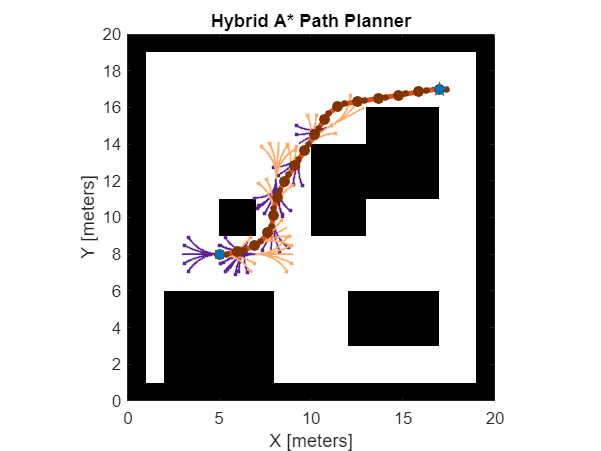

show(planner)


Data = [refpath.States(:,1) refpath.States(:,2)]

Data =     5.0000    8.0000
    5.9896    8.1244
    6.9177    8.4897
    7.6418    9.1642
    7.9538   10.1034
    8.1479   11.0817
    8.5779   11.9816
    9.1182   12.8231
    9.6585   13.6646
   10.1988   14.5060
